# Neural-Network 

Created time : 2024/5/10 09:41

學號 : 109321019    姓名 : 涂价弘

## Practice

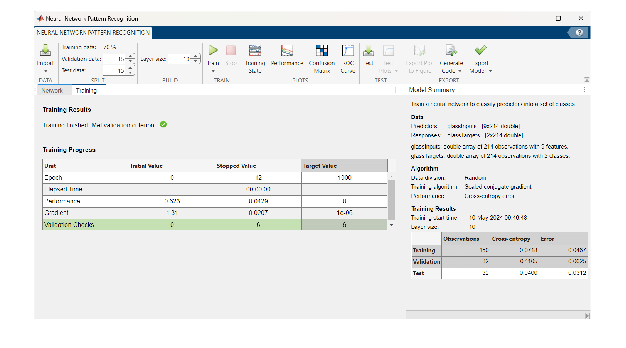

% nprtool
I = imread('./screenshot/neural_network_practice_1.png');
imshow(I)

## Exercise-1

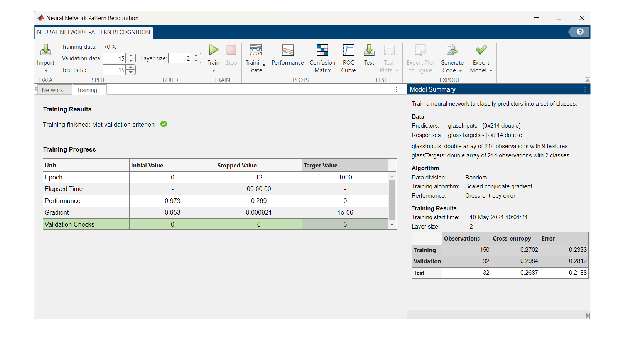

% nprtool
I = imread('./screenshot/neural_network_exercise_1.png');
imshow(I)

% 減少 layer size => loss error increase

## Exercise-2

### Load data

1. sepal length in cm

2. sepal width in cm

3. petal length in cm

4. petal width in cm

5. class: 

  -- Iris Setosa

  -- Iris Versicolour

  -- Iris Virginica

opts = delimitedTextImportOptions("NumVariables", 5);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["VarName1", "VarName2", "VarName3", "VarName4", "Irissetosa"];
opts.VariableTypes = ["double", "double", "double", "double", "categorical"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Irissetosa", "EmptyFieldRule", "auto");

% Import the data
iris = readtable("C:\Users\User\Desktop\Matlab\Digital_Image_Processing\data\iris\iris.data", opts)

iris = 151×5 table
    VarName1    VarName2    VarName3    VarName4    Irissetosa 
    ________    ________    ________    ________    ___________

      5.1         3.5         1.4         0.2       Iris-setosa
      4.9           3         1.4         0.2       Iris-setosa
      4.7         3.2         1.3         0.2       Iris-setosa
      4.6         3.1         1.5         0.2       Iris-setosa
        5         3.6         1.4         0.2       Iris-setosa
      5.4         3.9         1.7         0.4       Iris-setosa
      4.6         3.4         1.4         0.3       Iris-setosa
        5         3.4         1.5         0.2       Iris-setosa
      4.4         2.9         1.4         0.2       Iris-setosa
      4.9         3.1         1.5         0.1       Iris-setosa
      5.4         3.7         1.5         

### Preprocessing

data = [ table2array(iris(:,1:4)) double(table2array(iris(:,5))) ];

% Fix data errors
data(35, :) = double([4.9 3.1 1.5 0.2 1.0]);
data(38, :) = double([4.9 3.6 1.4 0.1 1.0]);
data = rmmissing(data);

% features
predicator = data(:, 1:4)';
% target
response = data(:, 5)';

% one-hot encoding
R = zeros(3, size(response, 2));
for i=1:3
R(i, response == i) = 1;
end

### Training

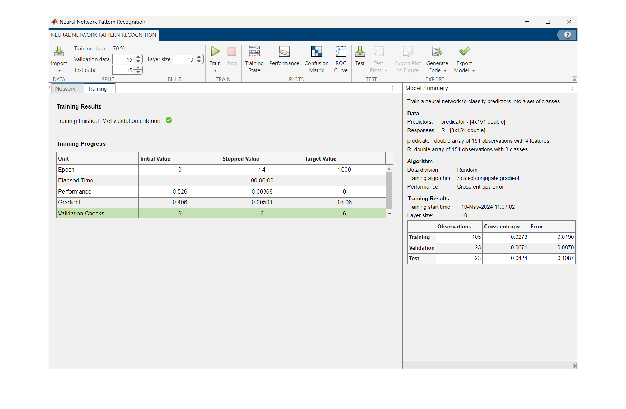

% nprtool

training_img = imread('./screenshot/neural_network_exercise_2.png');
performance_img = imread('./screenshot/neural_network_exercise_2_2.png');
imshow(training_img)

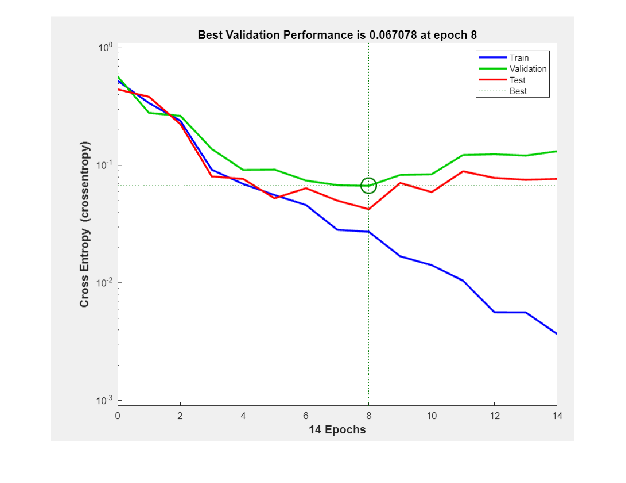

imshow(performance_img)

## Gradient Descent

[X, Y] = meshgrid(-10:10, -10:10);
L = (X - 2).^2 + (Y - 3).^2;
mesh(X, Y, L);
xlabel('x'), ylabel('y'), zlabel('L')

### Initial point

hold on
x0 = -10;
y0 = -10;
L0 = (x0 - 2).^2 + (y0 - 3).^2;
plot3(x0, y0, L0, 'or')
hold off

% dL/dx = 2(x-2), dL/dy = 2(y-3)
dx = 2 * (x0 - 2);
dy = 2 * (y0 - 3);

### 100 iteration with learning rate

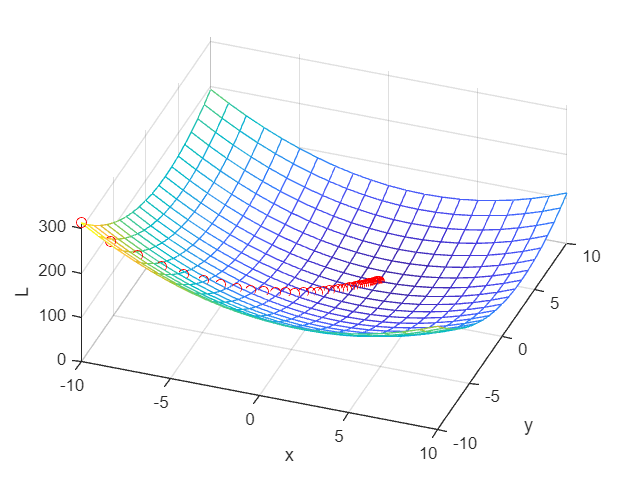

lr = 0.05;

hold on

x = zeros(100);
y = zeros(100);

x(1) = -10;
y(1) = -10;
L(1) = (x(1) - 2).^2 + (y(1) - 3).^2;
plot3(x(1), y(1), L(1), 'or')

for i = 2:100
    dx = 2 * (x(i - 1) - 2);
    dy = 2 * (y(i - 1) - 3);
    x(i) = x(i - 1) - dx * lr;
    y(i) = y(i - 1) - dy * lr;
    L(i) = (x(i) - 2).^2 + (y(i) - 3).^2;
    plot3(x(i), y(i), L(i), 'or')
end

hold off

view([20 55])